clear
load workspaces/3UAV_6users/PartB.mat

A_init = sol.A;
P_init;
Q_init = sol2.Q;
global history;
history.x = [];
history.fval = [];
global stopping;
stopping.x = [];
stopping.fval = [];

obj = PowerOptimization(A_init, P_init, Q_init, K, M, N, Rho0, H, W, NoisePower, d_min);
obj

obj = 1.7377

P = optimvar('P', M, N, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', Pmax);

[f3, power_constraint] = fcn2optimexpr(@PowerOptimization,A_init, P, Q_init, K, M, N, Rho0, H, W, NoisePower, d_min);
f3;

problem3 = optimproblem('ObjectiveSense', 'max');
problem3.Objective = f3;

options = optimoptions('fmincon', 'OutputFcn',@outfun, 'Display', 'iter', 'MaxFunctionEvaluations', 50000, 'OptimalityTolerance', 1.0000e-06, "Algorithm","interior-point", "StepTolerance",0);

problem3.Constraints.power_constraint = power_constraint <= Pmax;

show(problem3)


  OptimizationProblem : 

	Solve for:
       P

	maximize :
       [argout,~] = PowerOptimization(extraParams{1}, P, extraParams{2}, 6, 3, 150, 1e-06, 100, extraParams{3},
     1e-14, 100)

       

x2.P = P_init;

Solving problem using fmincon.
Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     451   -1.725718e+00    0.000e+00    5.500e-02
    1     902   -1.749155e+00    0.000e+00    2.739e-02    1.218e-01
    2    1353   -1.853649e+00    0.000e+00    2.669e-02    6.978e-02
    3    1812   -1.862042e+00    0.000e+00    1.031e-01    8.633e-03
    4    2264   -1.868225e+00    0.000e+00    1.029e-01    1.766e-02
    5    2716   -1.857695e+00    0.000e+00    4.104e-01    2.158e-01
    6    3167   -1.872570e+00    0.000e+00    1.499e-01    1.522e-01
    7    3618   -1.888094e+00    0.000e+00    2.275e-01    4.198e-02
    8    4069   -1.914948e+00    0.000e+00    2.297e-01    6.561e-02
    9    4522   -1.934763e+00    0.000e+00    1.680e-01    4.925e-02
   10    4982   -1.937556e+00    0.000e+00    7.589e-02    2.986e-03
   11    5441   -1.939491e+00    0.000e+00    3.555e-01    1.464e-03
   12    5901   -1.939454e+00    0.000e+00    1

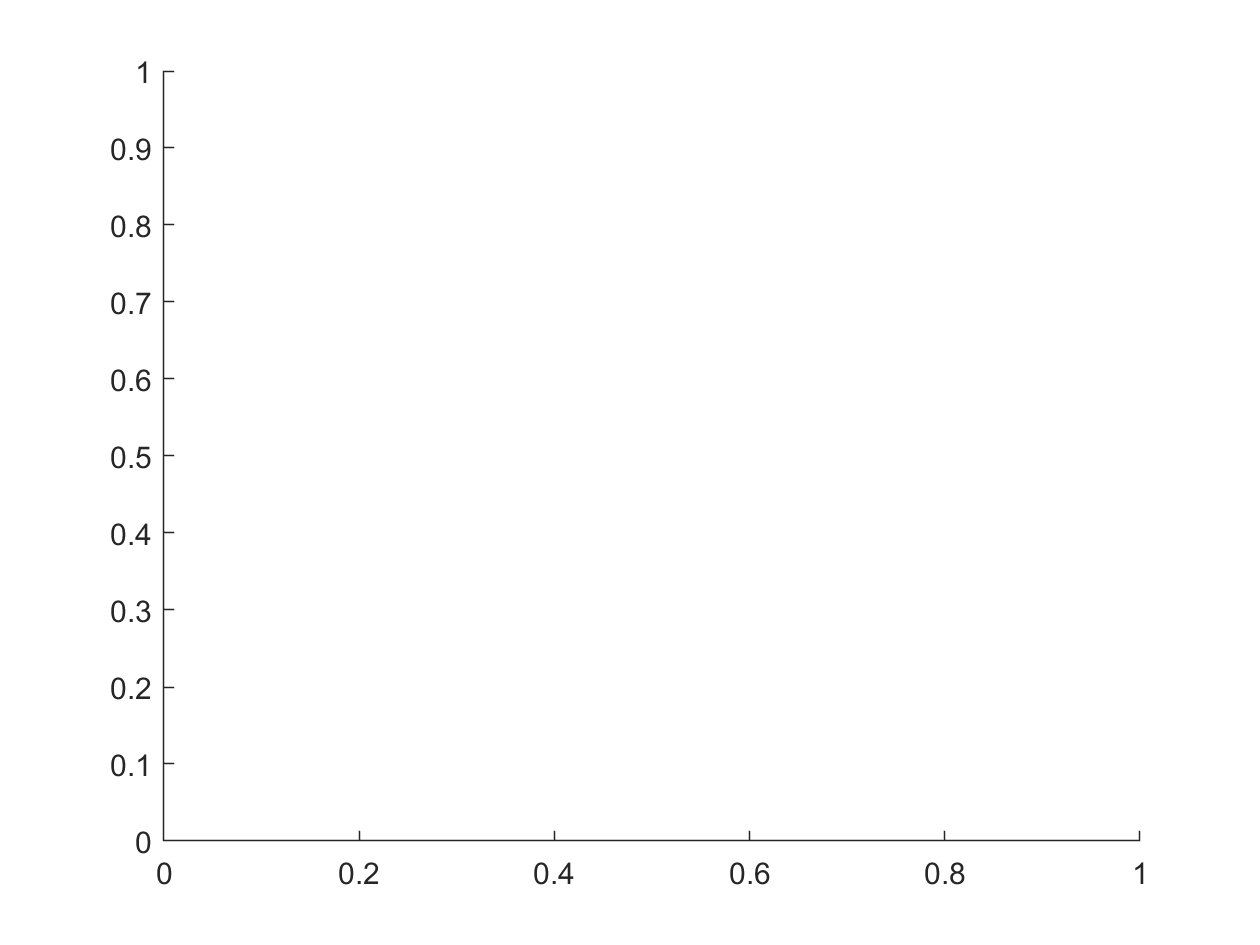


Feasible point with lower objective function value found.


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 5.000000e+04.



[sol3, fval3, exitflag3, output3] = solve(problem3, x2, 'Options', options);

P_init = sol3.P;

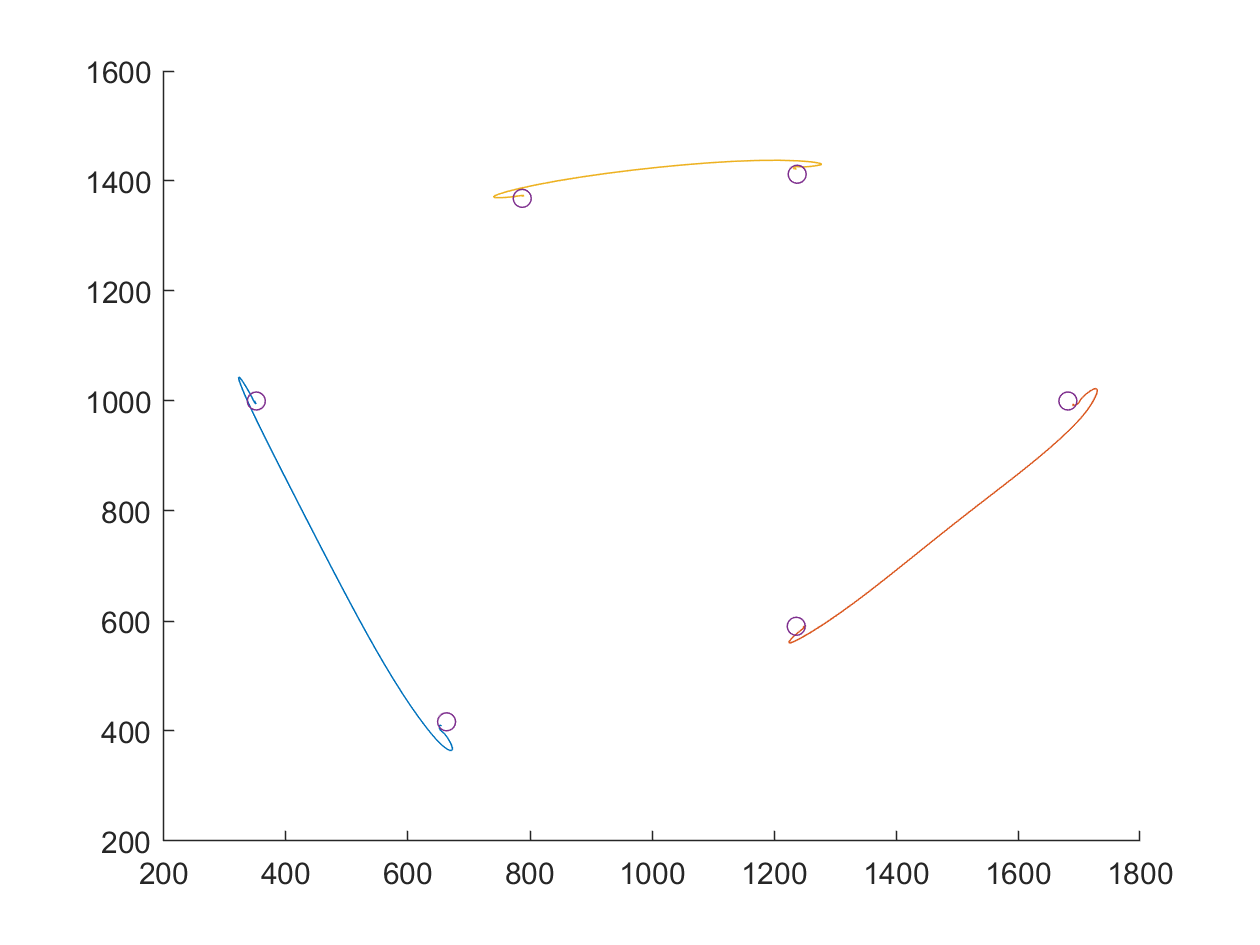

Q2 = sol2.Q;
%Q2 = Q_test;
Xs = Q2(:, 1, :);
Ys = Q2(:, 2, :);
Xs = reshape(Xs,[M,N]);
Ys = reshape(Ys, [M,N]);
for i = 1:M
    hold on
    plot(Xs(i,:), Ys(i,:));
end
scatter(W(:,1), W(:,2));
hold off

clf
